## 1.Pixel operation

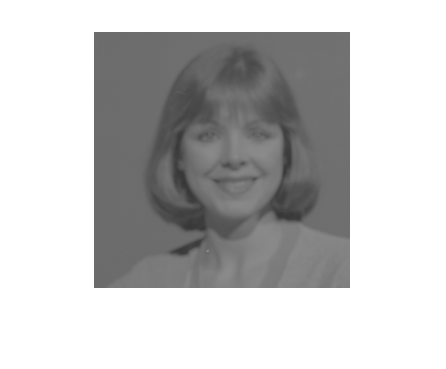

im = imread("wom1.PNG");
imshow(im);

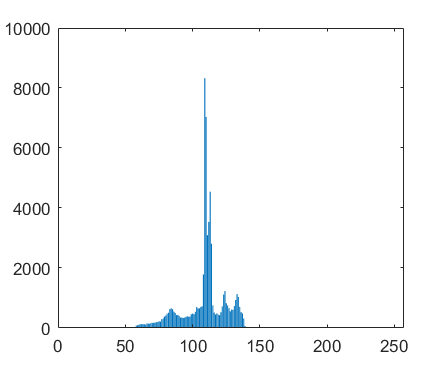


%doc sum
% retirm a row vector tht containing the sum of each columns.
im_hist = sum((0:255) == im(:),1);
bar(im_hist);

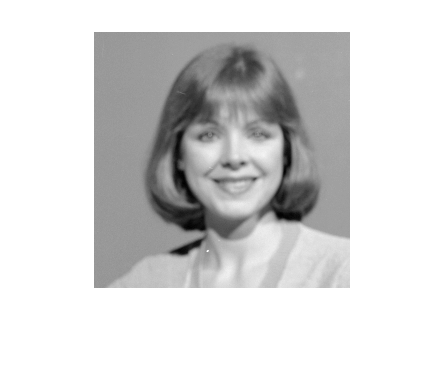

im_constrast_stretch = ContrastStretch(im);
im_constrast_stretch_hist = sum((0:255) == im_constrast_stretch(:),1);
figure,imshow(im_constrast_stretch);

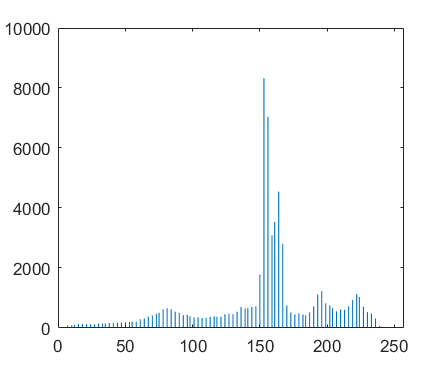

bar(im_constrast_stretch_hist);

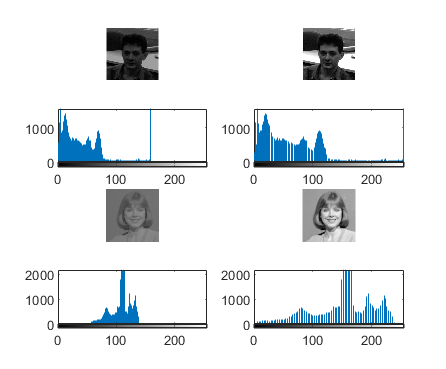

man_temp = imread('man8.PNG'); %read the image 
wom_temp = imread('wom1.PNG');
man_new = ContrastStretch(man_temp);
won_new = ContrastStretch(wom_temp);

subplot(4,2,1);
imshow(man_temp);       % display original image

subplot(4,2,2);
imshow(man_new);   % display transformed image

subplot(4,2,3);
imhist(man_temp);

subplot(4,2,4);
imhist(man_new);


subplot(4,2,5);
imshow(wom_temp);       % display original image

subplot(4,2,6);
imshow(won_new);   % display transformed image

subplot(4,2,7);
imhist(wom_temp);

subplot(4,2,8);
imhist(won_new);

## 2. Down sampling

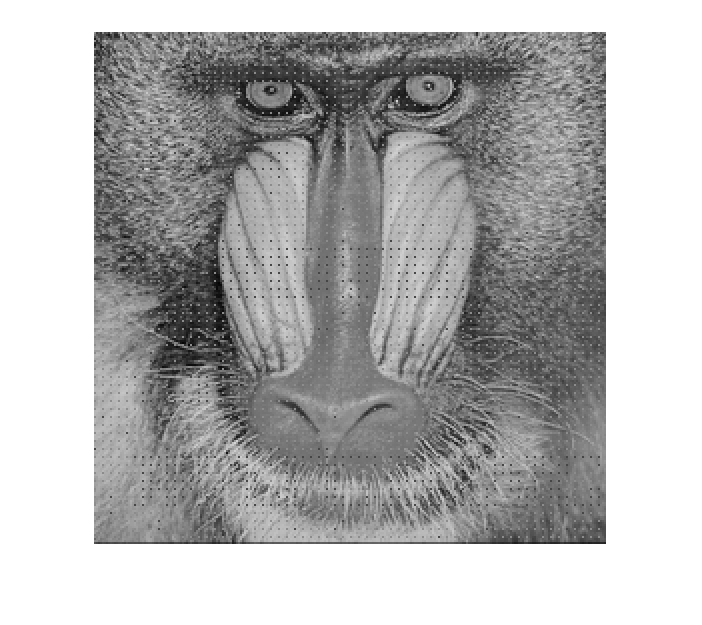

% im = imread("mbaboon.bmp");
% c = mat2cell(im,[4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4] ...
%     ,[4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4]);
% % c
% % c1 = mat2cell(i,[64 64 64 64] ...
% %     ,[64 64 64 64]);
% 
% 
% % result = zeros(size(im));
% 
% [q,r,~] = size(c);
% 
% for i=1:q
%     for j=1:r
%         block_struct = c{i,j}
%         fun = @(block_struct) downsample(block_struct)
%         result = blockproc(block_struct,[4 4],fun);        
%     end
% end
figure,
im = imread('mbaboon.bmp');
title('Original')
imshow(im, 'InitialMagnification', 500);

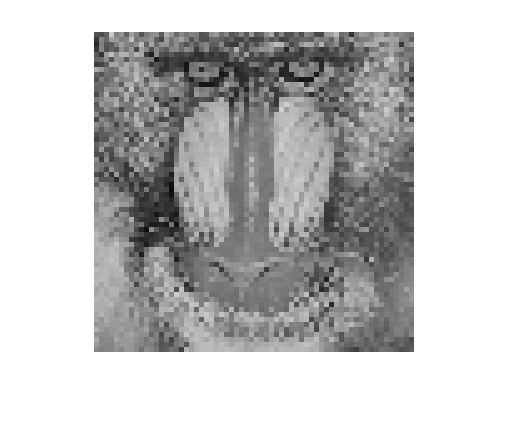


fun_replace_2x2 = @(block_struct) block_struct.data(2, 2);

im_replace_2x2 = blockproc(im, [4 4], fun_replace_2x2);
imshow(im_replace_2x2, 'InitialMagnification', 500);

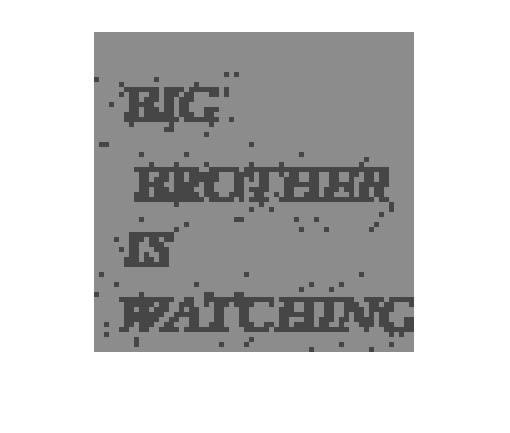

fun_replace_1x1 = @(block_struct) block_struct.data(1, 1);

im_replace_1x1 = blockproc(im, [4 4], fun_replace_1x1);
imshow(im_replace_1x1, 'InitialMagnification', 500);

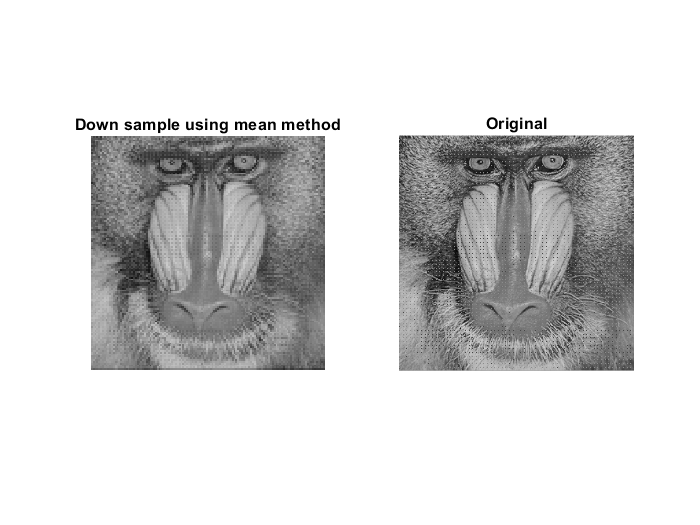

fun_mean = @(block_struct) cast(mean(block_struct.data(:), 'all'), 'uint8');
figure,
im_down_sample_mean = blockproc(im,[2 2],fun_mean);

subplot(1,2,1);

imshow(im_down_sample_mean,'InitialMagnification',500);
title('Down sample using mean method')
subplot(1,2,2);

imshow(im,'InitialMagnification',500);
title('Original')

## 3. Visual perception

When that person suddenly going to a dark theater, the brightness of surrounding objects change quickly, so it takes for a while for the eyes to adapt with this major change (for e.g : increasing the pupil size).

%Light adaptation

## 4.Histogram

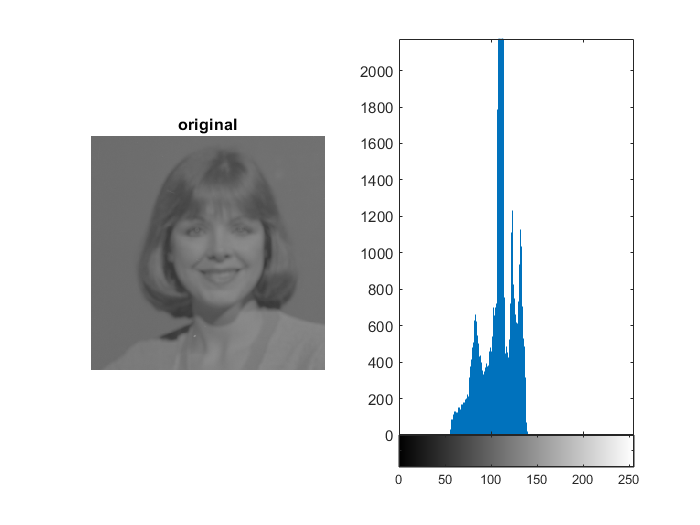

im4 = imread('wom1.PNG');
figure;
subplot(1, 2, 1)
imshow(im4);title('original')
subplot(1, 2, 2)
imhist(im4);

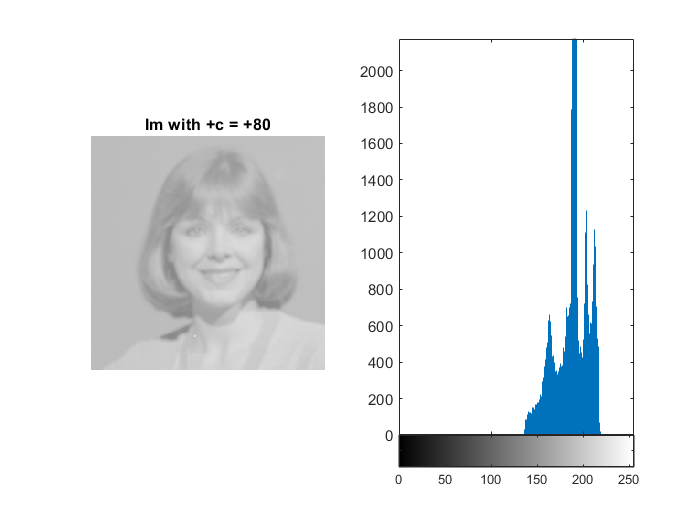


c_pos = 80;
im_shift_pos = c_pos + double(im4);
im_shift_pos = cast(min(im_shift_pos,255),'uint8');
figure;
subplot(1, 2, 1)
imshow(im_shift_pos);title('Im with +c = +80')
subplot(1, 2, 2)
imhist(im_shift_pos);

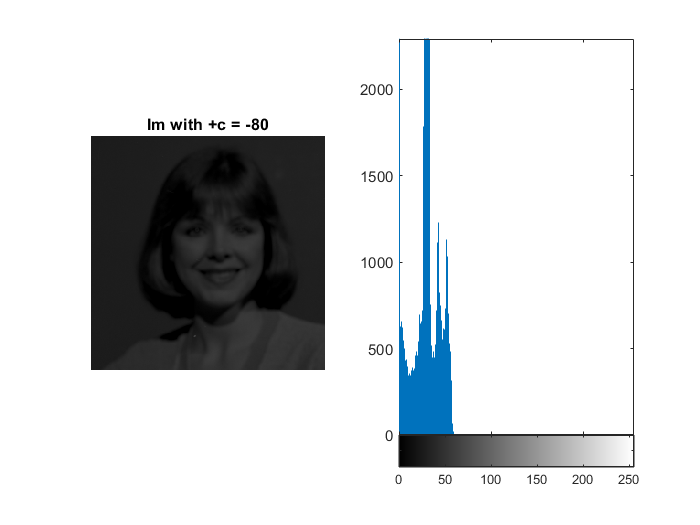


c_nev = -80;
im_shift_nev = c_nev + double(im4);
im_shift_nev = cast(max(im_shift_nev,0),'uint8');
figure;
subplot(1, 2, 1)
imshow(im_shift_nev);title('Im with +c = -80')
subplot(1, 2, 2)
imhist(im_shift_nev);

## b

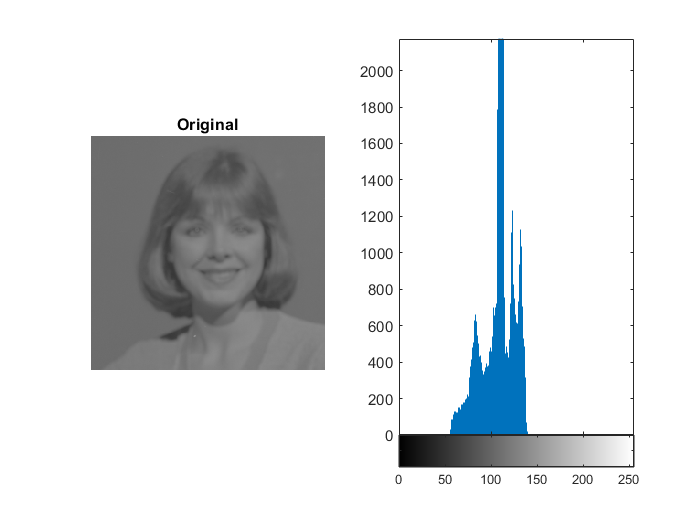

% original = 1
figure;
subplot(1, 2, 1)
imshow(im4);
title('Original')
subplot(1, 2, 2)
imhist(im4);

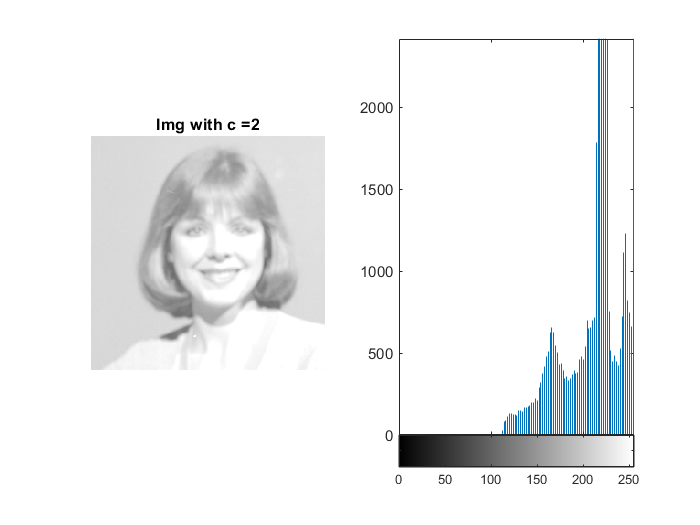


c_mul_stretch = 2;
im_stretch = c_mul_stretch * double(im4);
im_stretch = cast(min(im_stretch, 255), 'uint8');

figure;
subplot(1, 2, 1)
imshow(im_stretch);title('Img with c =2')
subplot(1, 2, 2)
imhist(im_stretch);

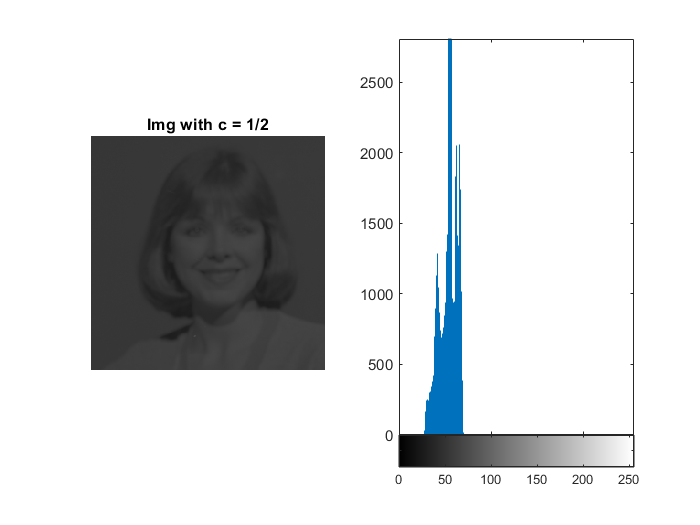


c_mul_shrink = 0.5;
im_shrink = c_mul_shrink * double(im4);
im_shrink = cast(im_shrink, 'uint8');

figure;
subplot(1, 2, 1)
imshow(im_shrink);title('Img with c = 1/2')
subplot(1, 2, 2)
imhist(im_shrink)

## c

im4 = imread('wom1.PNG');
im_rot90 = imrotate(im4, 90);

figure;
subplot(1, 2, 1)
imshow(im4);title('Original')
subplot(1, 2, 2)
imhist(im4);

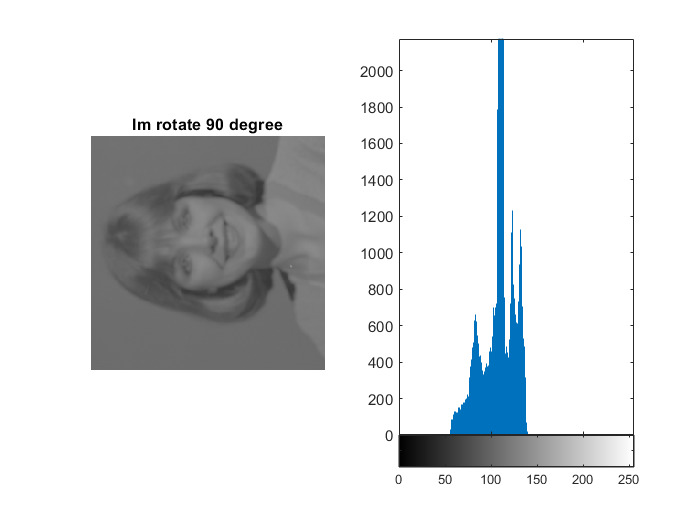


figure;
subplot(1, 2, 1)
imshow(im_rot90);title('Im rotate 90 degree')
subplot(1, 2, 2)
imhist(im_rot90);

%% doc cast -- Convert variable to different data type B=cast(A,new_class)